#### Limpieza inicial y Valores inicales

clc
clear

%Propiedades del medio
mu = 4*pi*1e-7;                      % Permeabilidad del medio
g = 9.81;                       % Constante de gravedad(m/s^2)

%Valores de la espira de la espira
N=40;                         % Cantidad de espiras (30)
Ohm = .1;                     % Resistencia de la espira (0.05)
R= .02;                        % Radio de la espira (m) (0.01)
%
% Propiedades del dipolo
M = 3;                             % Momento magnético dipolar (Am^2) 30
m = .005;                           % Masa del dipolo magnético (kg) 0.003

% Constantes
km = 9*(mu^2)*(M^2)*(R^4)*(N^2)/(4*m*Ohm);
km2 = 3*mu*M*N*(R^2)/(2*Ohm);
%Condiciones iniciales
v0 = 0;% 0
z0 = .05;% 0.05
% Tiempo de simulación
tt = 1.0; %1.2

#### Funciones para las ecuaciones del movimiento


% Solución del sistema de ecuaciones diferenciales
A = @(z, v) - g - (km * (z.^2)./((R.^2 + z.^2).^5)) .* v;

%https://la.mathworks.com/help/matlab/ref/ode45.html
dydt = @(t, y) [y(2); A(y(1), y(2))];

[t,y] = ode45(dydt,[0 tt],[z0; v0]); %fem

z = y(:,1);
v = y(:,2);
a = A(z, v);
f = m*a;
I = km*z.*v./((R*R+z.*z).^(2.5));

%Calculos finales


#### Gráficas

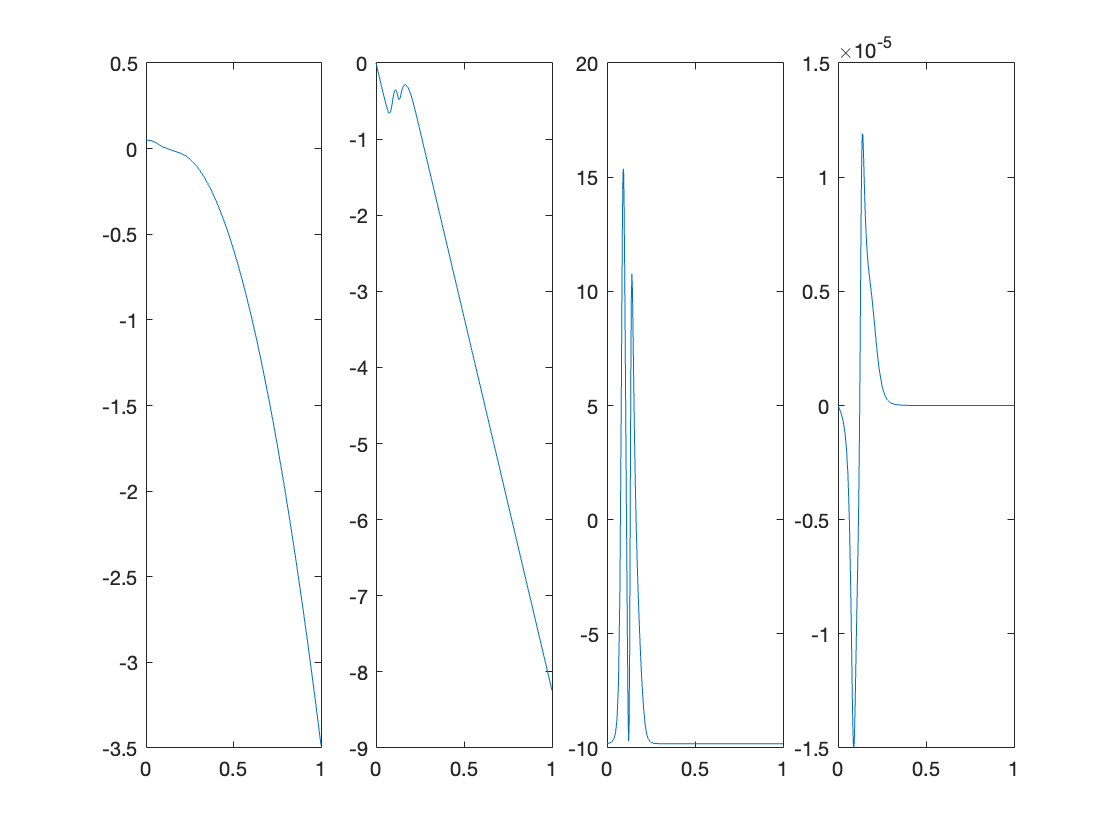

subplot(1,4,1); 
plot(t,z);
subplot(1,4,2); 
plot(t,v);
subplot(1,4,3); 
plot(t,a);
subplot(1,4,4); 
plot(t,I);